# Hands-on 03

## 1 Time to frequency and frequency to time

### 1.1 Toolbox: Spectrum

The key element in solving these problems is to identify the link between the indices of the vectors you are handling and the physical domain - i.e., How long in time is my vector of length <N>? Which frequency does index <M> in my frequency vector correspond to?

Here some hints and snipplets to help you on the way.

% some parameters and preps
fs = ;             % sampling frequency
T = ;                % duration in time (which we'll calculate below to check)
n = randn(fs*T, 1);    % some random vector

% identify the length of the vector
len_n_samples = length(n);      % in samples
len_n_s = length(n)/fs         % in time

len_n_s = 0.1000

Now we might know the duration of the signal. How was that again connected to the frequency resolution? This might be handy when calculating a frequency vector that we use for plotting out computed spectra

% calculate the frequency vector
T0 = length(n)/fs;      % duration of the signal in s
delta_f = 1/T0;         % frequency resolution

Now things are getting a bit tricky. Remember that we are sampling one period of the spectrum. With the implementation of MATLAB, we start with frequency 0 and then walk up in frequency. So one way is to sample the period from [0 fs]. but we somewhat know that there is something called the NYQUIST frequency at fs/2. so it is actually instructive to build the frequency vector "by hand". 

Below is the example of having an even number of samples (write the other!). You will have to distinguish between even and odd numbers - because you will (or not) hit the Nyquist frequency on the way - and you don't sample fs/2 and -fs/2 as they belong to different periods of the spectrum!

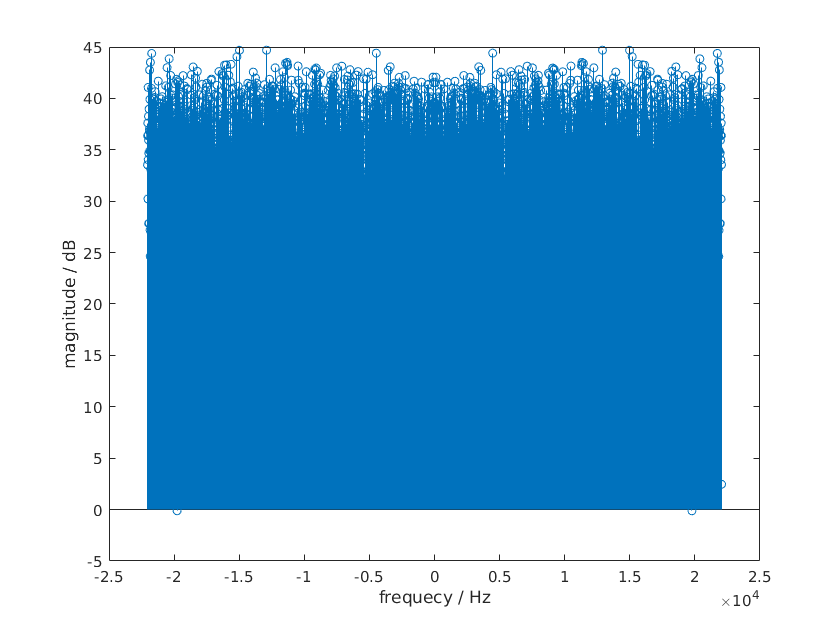

% get the positive frequencies first
f_pos = 0:delta_f:fs/2;         % we'll hit fs/2
f_neg = -fs/2+delta_f:delta_f:-delta_f; % so we come from the back towards 0

% Now we can calculate the spectrum of out signal and plot it on a
% meaningful axis!
Y = fft(n);

stem([f_pos f_neg], 20*log10(abs(Y)))
xlabel('frequecy / Hz')
ylabel('magnitude / dB')

- Change the duration of the signal and check the difference between two frequency bins

- change the sampling frequency and see how the picture changes